# EX. 3. 

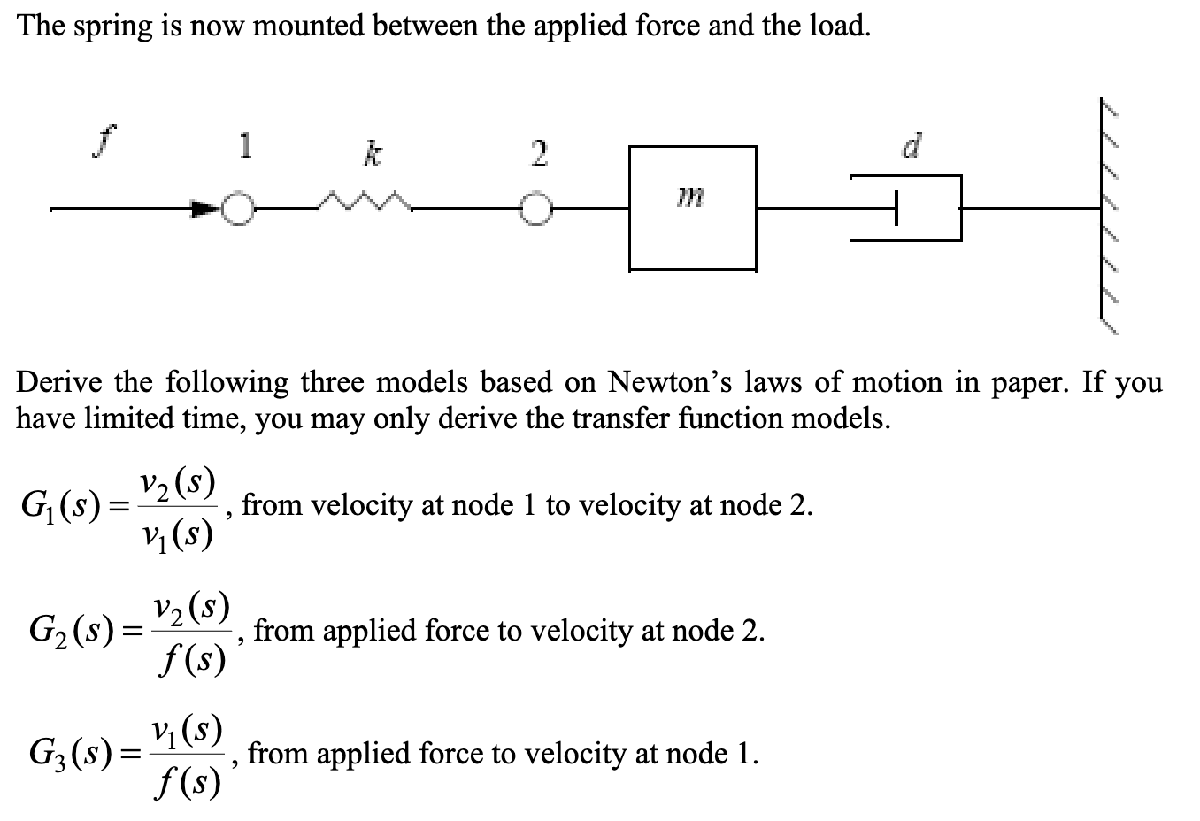

### Basic parameters

The basic parameters of the system are given in the problem description

m = 0.1; % kg
d = 0.5; % Ns/m
k = 8; % N/m

### Transfer function models

The transfer functions were derived on paper according to the following: 


$$G_1(s) = \frac{k}{ms^2 +ds + k}
$$



$$G_2(s) = \frac{1}{ms + d}
$$



$$G_3(s) = \frac{ms^2 + ds + k}{k(ms + d)}
$$


s = tf('s');

% Derived transfer function model from velocity at node 1 to velocity at
% node 2
G1 = k / (m*s^2 + d*s + k);

% Derived transfer function model from force to velocity at node 2
G2 = 1 / (m*s + d);

% Derived transfer function model from force to velocity at node 1
G3 = (m*s^2 + d*s + k) / (k*(m*s + d));

### Bode plots of transfer functions

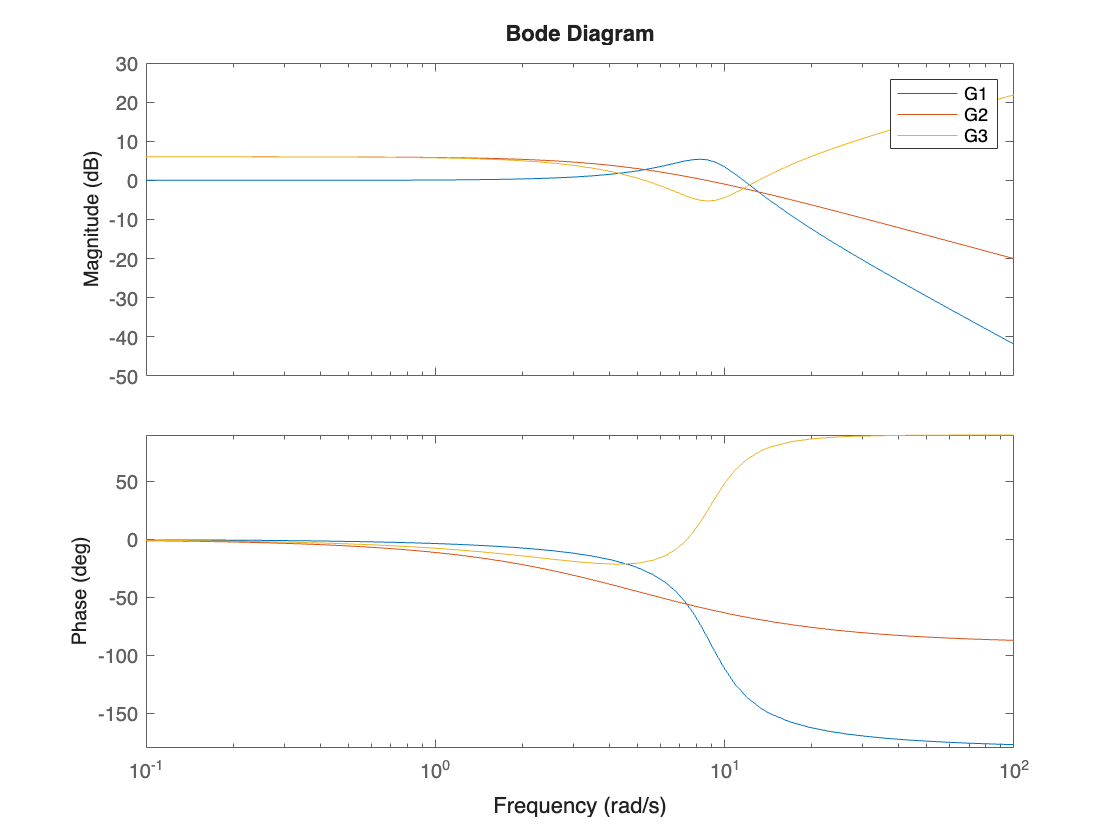

figure;
bode(G1, G2, G3)
legend("G1", "G2", "G3")

As we can see in this bode diagram, G1 and G2 follows the expected shape for a second order (G1) and first order (G2) transfer function. However, G3 exhibits very strange behavior with a plot that appears similar to an inverted G1 plot. Instead of having a low-pass character where the amplitude is reduced as the frequency increases, the amplitude instead increases with higher frequencies. Instead of having a resonance peak, the plot instead shows a resonance dip for G3. This is because G3 is not a proper transfer function. A proper transfer function is defined as $G(s) = \frac{N(s)}{D(s) $ where the relative degree between denominator and numerator is described by $n_A = n_D - n_N$. If $n_A < 0$ the transfer function is not proper, the gain at high frequencies is infinite and we cannot make a step response for that system. In G3, $n_A = -1$which is not proper. 

### Pole-zero plot of transfer functions

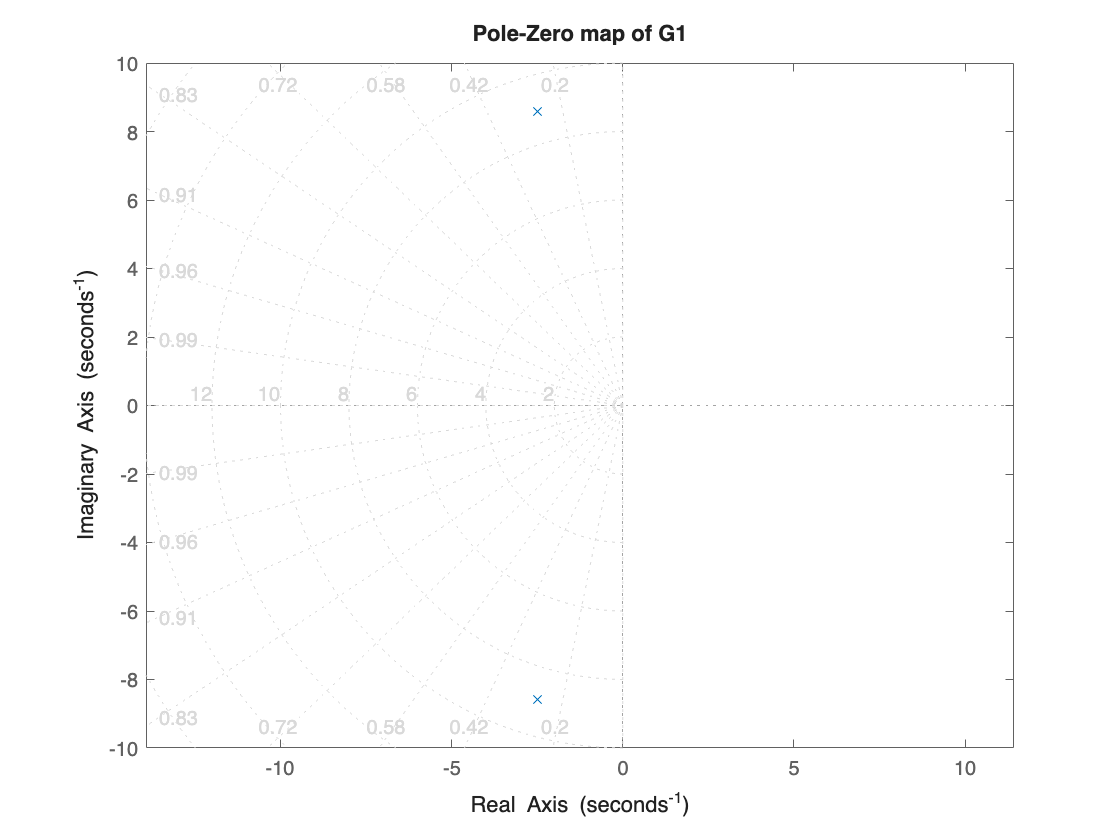

figure;
pzp1 = pzplot(G1); axis equal; grid on
title("Pole-Zero map of G1");

From this pole-zero plot of G1 we can see that it has complex conjugate poles. This means that the system will have a resonance frequency which we can also see in the bode plot. It also means that the system will have an oscillatory response to a step input. 

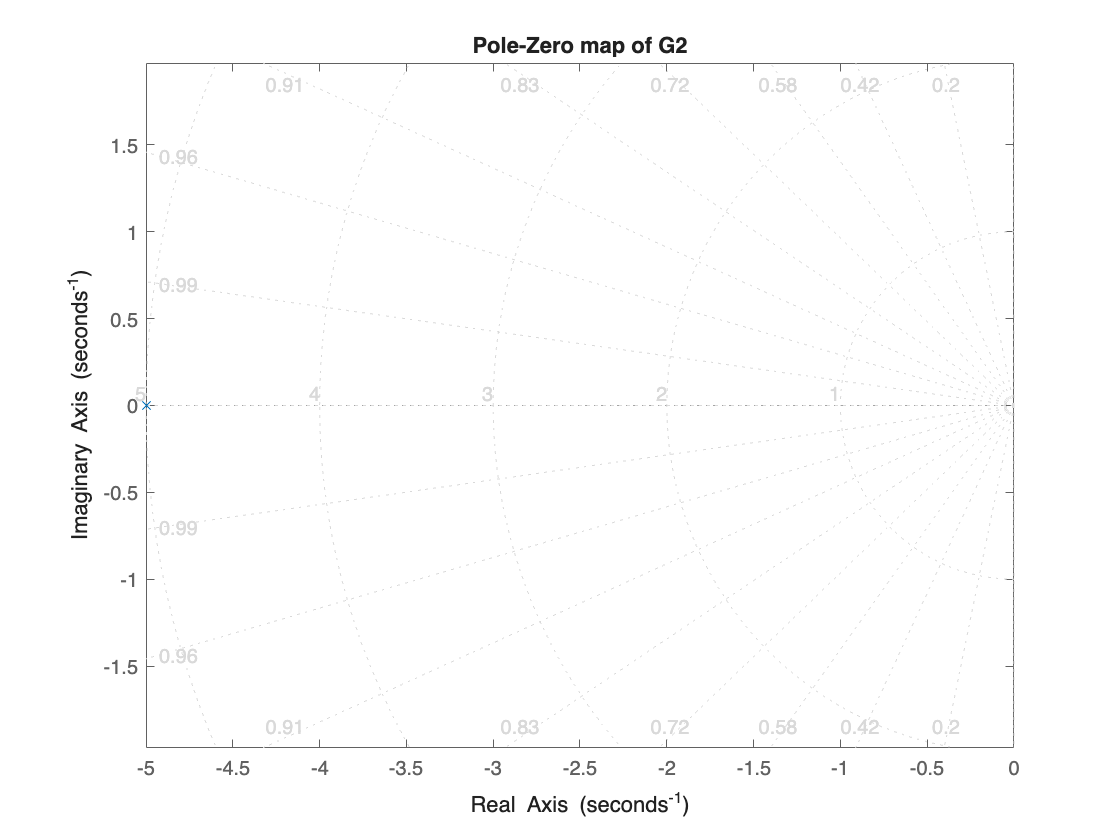

figure;
pzp2 = pzplot(G2); axis equal; grid on
title("Pole-Zero map of G2");

From this pole-zero plot of G2 we can see that the system has only one negative and real pole. This means that the system will not have a resonance frequency which we can also see in the bode plot. It also means that the system will have a transient response to a step input.

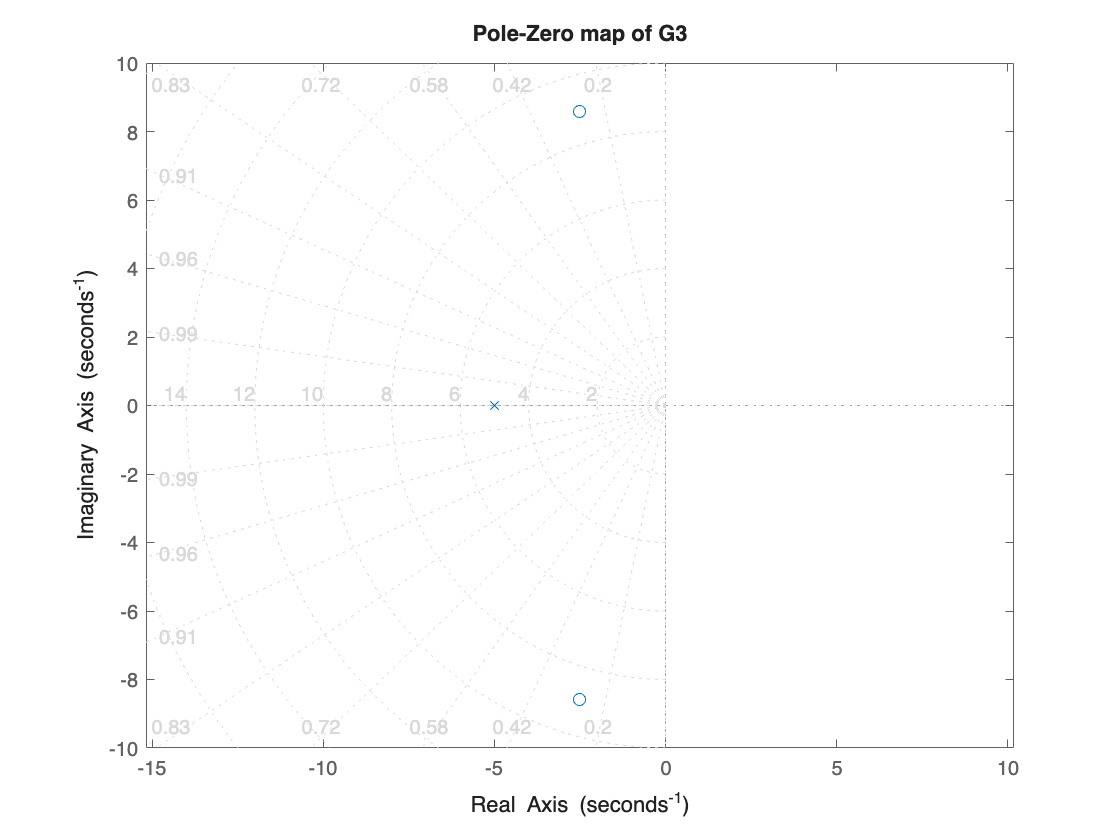

figure;
pzp3 = pzplot(G3); axis equal; grid on
title("Pole-Zero map of G3");

From the pole-zero plot of G3 we can see that the system has one negative real pole, but two complex conjugate zeroes. This indicates that the system is inproper and will have infinite gain at higher frequencies. 

### Step response from velocity at node 1 to velocity at node 2

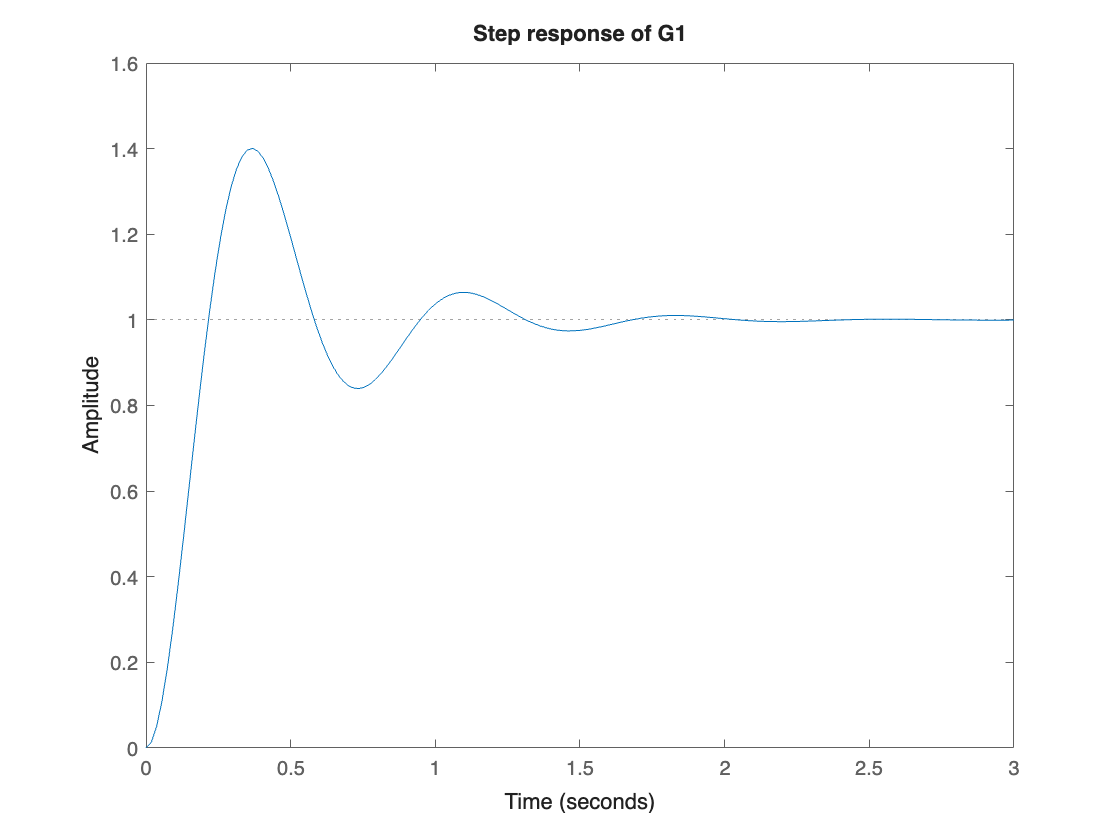

figure;
sp1 = stepplot(G1);
title("Step response of G1");

### Step response from force to velocity at node 2

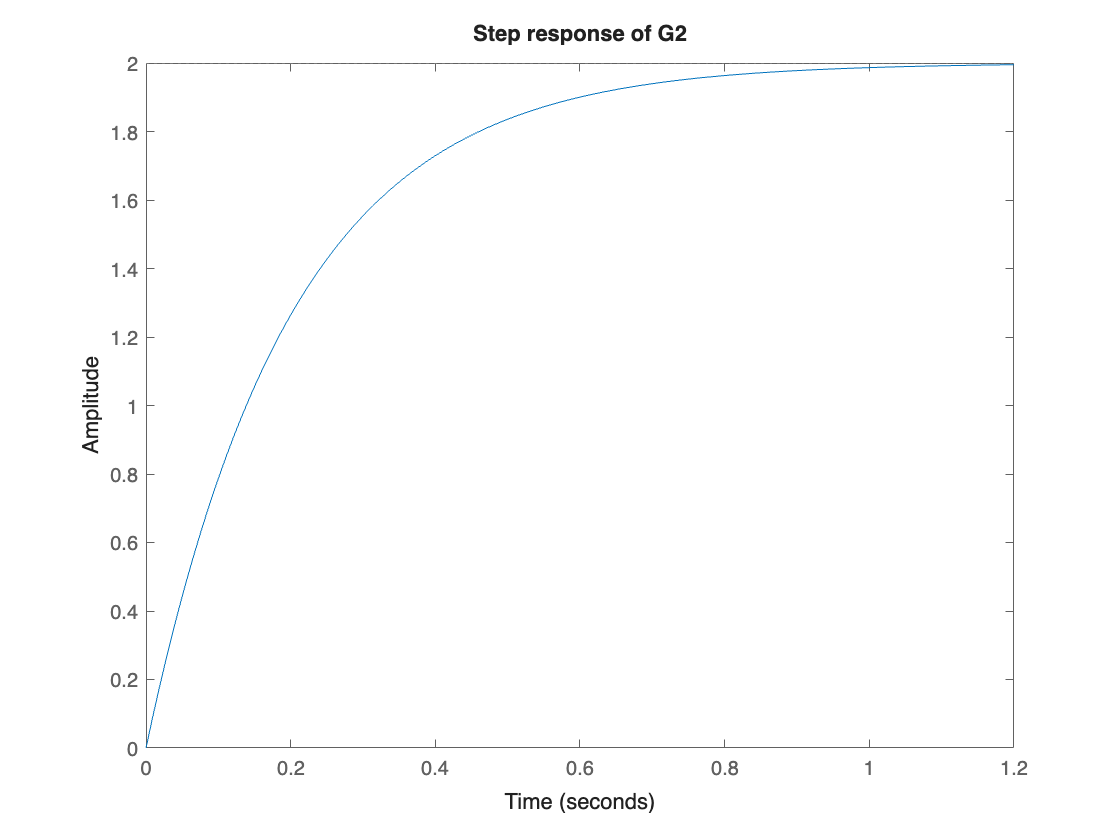

figure;
sp2 = stepplot(G2);
title("Step response of G2");

### Step response from force to velocity at node 1

G3 is an improper transfer function as the order of the numerator is higher than the order of the denominator. Because of this, a step response of the system can not be plotted.

### Simulink and simscape models

#### Step response of simulink transfer function and simscape model from force to velocity at node 2 with step input

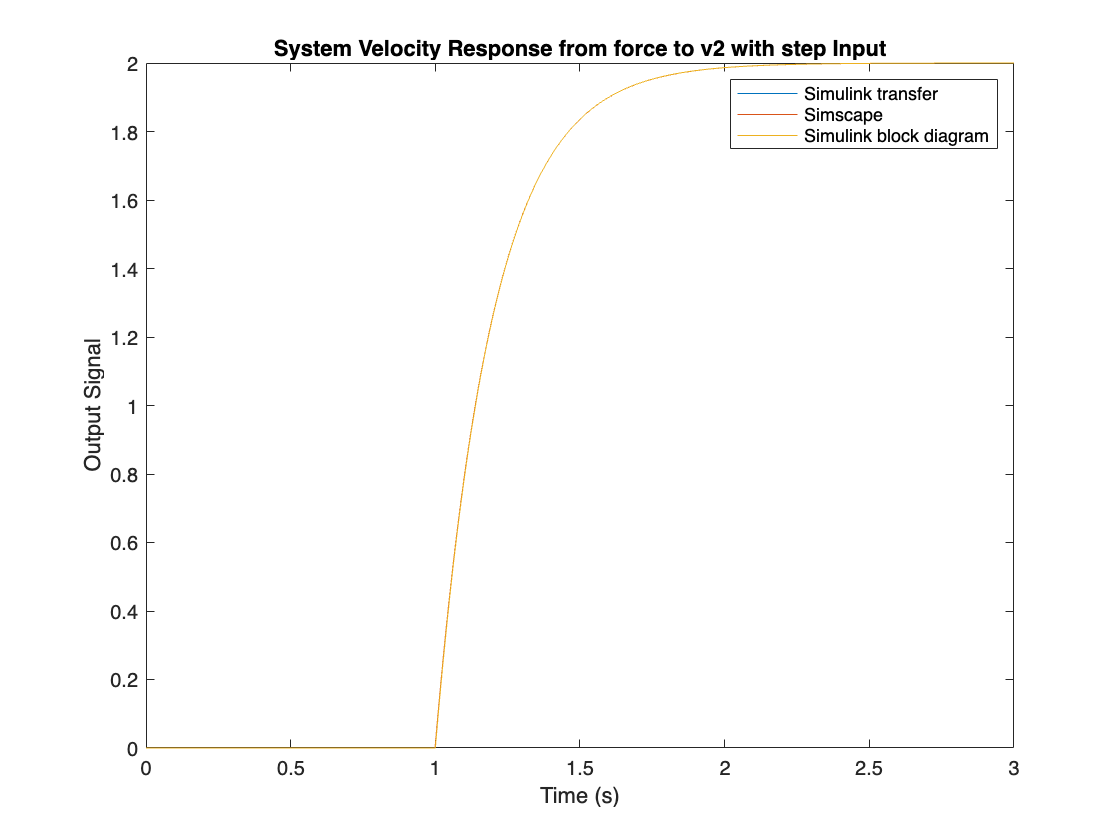

model_name = 'Part1_new2'; 
load_system(model_name);

runningtime = num2str(3);

set_param(model_name, 'StopTime', runningtime); 

input_type = 'step';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval2'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval2'], 'Value', '0');
        
        
        frequency = num2str(20); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave2'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time12 = simOut.tout;
output_signal12 = simOut.logsout.getElement('Velocity 2 Sim 2,3 Ex.3').Values.Data; 


model_name = 'excercise1_3tf2'; 
load_system(model_name);


set_param(model_name, 'StopTime', runningtime); 
set_param(model_name, 'Solver', 'ode45');
set_param(model_name, 'MaxStep', '0.001');

input_type = 'step';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = num2str(20); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time22 = simOut.tout;
output_signal22 = simOut.logsout.getElement('velocity').Values.Data; 

model_name = 'excercise1_3bd2'; 
load_system(model_name);

runningtime = num2str(3);

set_param(model_name, 'StopTime', runningtime); 
set_param(model_name, 'Solver', 'ode45');
set_param(model_name, 'MaxStep', '0.001');

input_type = 'step';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = num2str(20); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time23 = simOut.tout;
output_signal23 = simOut.logsout.getElement('v2').Values.Data;


figure;
plot(sim_time22, output_signal22);
title(['System Velocity Response from force to v2 with ' input_type ' Input']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on

runningtimeint = str2num(runningtime);
tvec = linspace(0,runningtimeint,length(output_signal12));

plot(tvec, output_signal12)
plot(sim_time23, output_signal23);
legend("Simulink transfer", "Simscape", "Simulink block diagram")
hold off

Plots for step response of the system from force to velocity at node 2 simulated using both simulink and simscape shown to give the same result. This result also corresponds with the result from the matlab stepplot function. Note that a 1s delay was added to the step input to correctly show system behavior of G3 in simscape. This is not part of the system response in this case and the plot can be assumed to start at 0 instead of 1. 

#### Step response of simulink transfer function and simscape model from velocity at node 1 to velocity at node 2 with step input

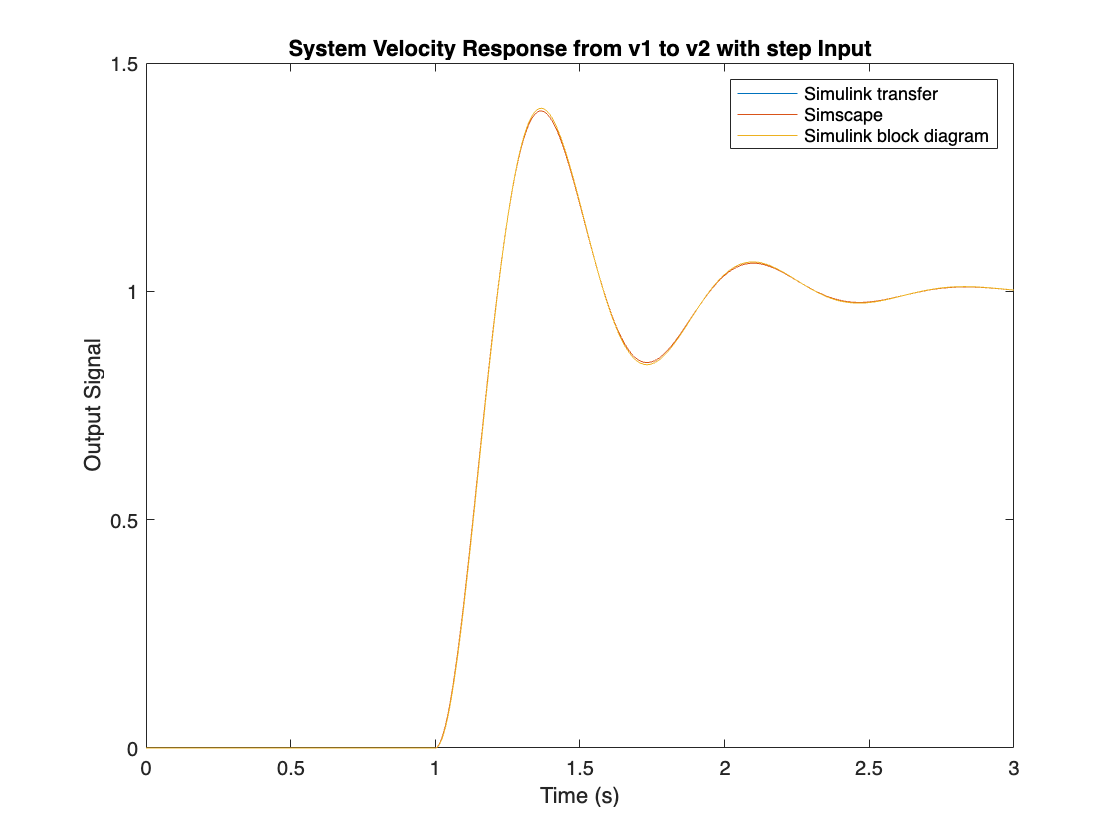

model_name = 'Part1_new2'; 
load_system(model_name);

runningtime = num2str(3);

set_param(model_name, 'StopTime', runningtime); 

input_type = 'step';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval2'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval2'], 'Value', '0');
        
        
        frequency = num2str(20); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave2'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time12 = simOut.tout;
output_signal12 = simOut.logsout.getElement('Velocity 2 Sim 1 Ex.3').Values.Data; 


model_name = 'excercise1_3tf1'; 
load_system(model_name);


set_param(model_name, 'StopTime', runningtime); 
set_param(model_name, 'Solver', 'ode45');
set_param(model_name, 'MaxStep', '0.001');

input_type = 'step';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = num2str(20); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time22 = simOut.tout;
output_signal22 = simOut.logsout.getElement('velocity').Values.Data; 

model_name = 'excercise1_3bd1'; 
load_system(model_name);

runningtime = num2str(3);

set_param(model_name, 'StopTime', runningtime); 
set_param(model_name, 'Solver', 'ode45');
set_param(model_name, 'MaxStep', '0.001');

input_type = 'step';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = num2str(20); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time23 = simOut.tout;
output_signal23 = simOut.logsout.getElement('v2').Values.Data;


figure;
plot(sim_time22, output_signal22);
title(['System Velocity Response from v1 to v2 with ' input_type ' Input']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on

runningtimeint = str2num(runningtime);
tvec = linspace(0,runningtimeint,length(output_signal12));

plot(tvec, output_signal12)
plot(sim_time23, output_signal23);
legend("Simulink transfer", "Simscape", "Simulink block diagram")
hold off

Plots for step response of the system from velocity at node 1 to velocity at node 2 simulated using both simulink and simscape shown to give the same result. This also corresponds to the response given by the matlab stepplot function. Note that a 1s delay was added to the step input to correctly show system behavior of G3 in simscape. This is not part of the system response in this case and the plot can be assumed to start at 0 instead of 1. 

#### Step response of simscape model from force to velocity at node 1 with step input

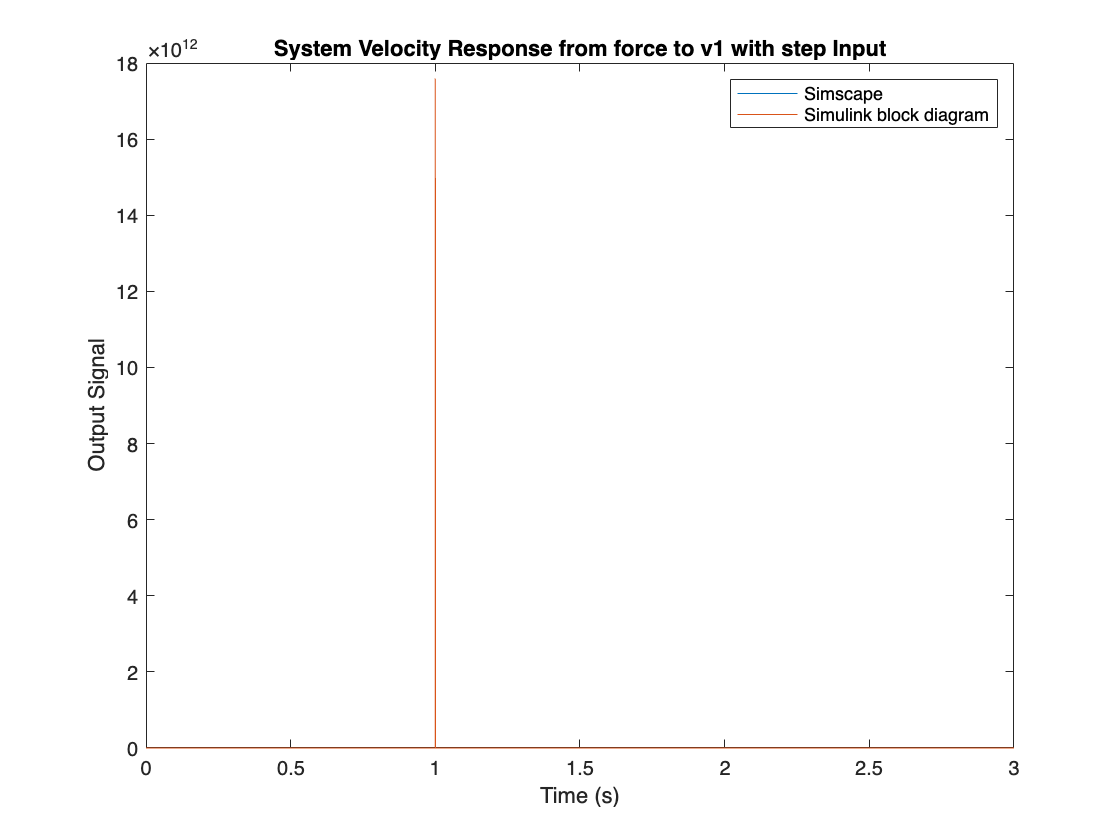

model_name = 'Part1_new2'; 
load_system(model_name);

runningtime = num2str(3);

set_param(model_name, 'StopTime', runningtime); 

input_type = 'step';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval2'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval2'], 'Value', '0');
        
        
        frequency = num2str(20); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave2'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time12 = simOut.tout;
output_signal12 = simOut.logsout.getElement('Velocity 1 Sim 2,3 Ex.3').Values.Data; 

model_name = 'excercise1_3bd2'; 
load_system(model_name);

runningtime = num2str(3);

set_param(model_name, 'StopTime', runningtime); 
set_param(model_name, 'Solver', 'ode45');
set_param(model_name, 'MaxStep', '0.001');

input_type = 'step';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = num2str(20); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time23 = simOut.tout;
output_signal23 = simOut.logsout.getElement('v1').Values.Data;

figure;

runningtimeint = str2num(runningtime);
tvec = linspace(0,runningtimeint,length(output_signal12));

plot(tvec, output_signal12)
hold on
plot(sim_time23, output_signal23)

legend("Simscape", "Simulink block diagram")
title(['System Velocity Response from force to v1 with ' input_type ' Input']);
xlabel('Time (s)');
ylabel('Output Signal');
hold off

In this graph, which could only be simulated in simscape and simscape block diagram as both the matlab step response function and the simulink transfer function block gave errors as there is technically no step response for G3, it is possible to see the effect of trying to measure the velocity at a massless point. There is an infinite acceleration and a velocity spike at point 1 when a force is applied to it. This spike is higher in the Simulink block diagram model than in the simscape model, but in the same location. The transfer function is an improper system which also illustrates how this system is technically physically impossible since no massless points can exist. 

### G3 simulated with sinusoidal input velocity

We elected to not plot every transfer function with sinusoidal input as this has already been done for similar systems in task 2, and it would clutter the document. However, studying the response of G3 to a sinusoidal input is very interesting given the infinite gain at infinite frequency. Below is the response to a sinusoidal input force of amplitude 1 in relation to velocity at point v1, first at 50 rad/s and then at 200 rad/s.

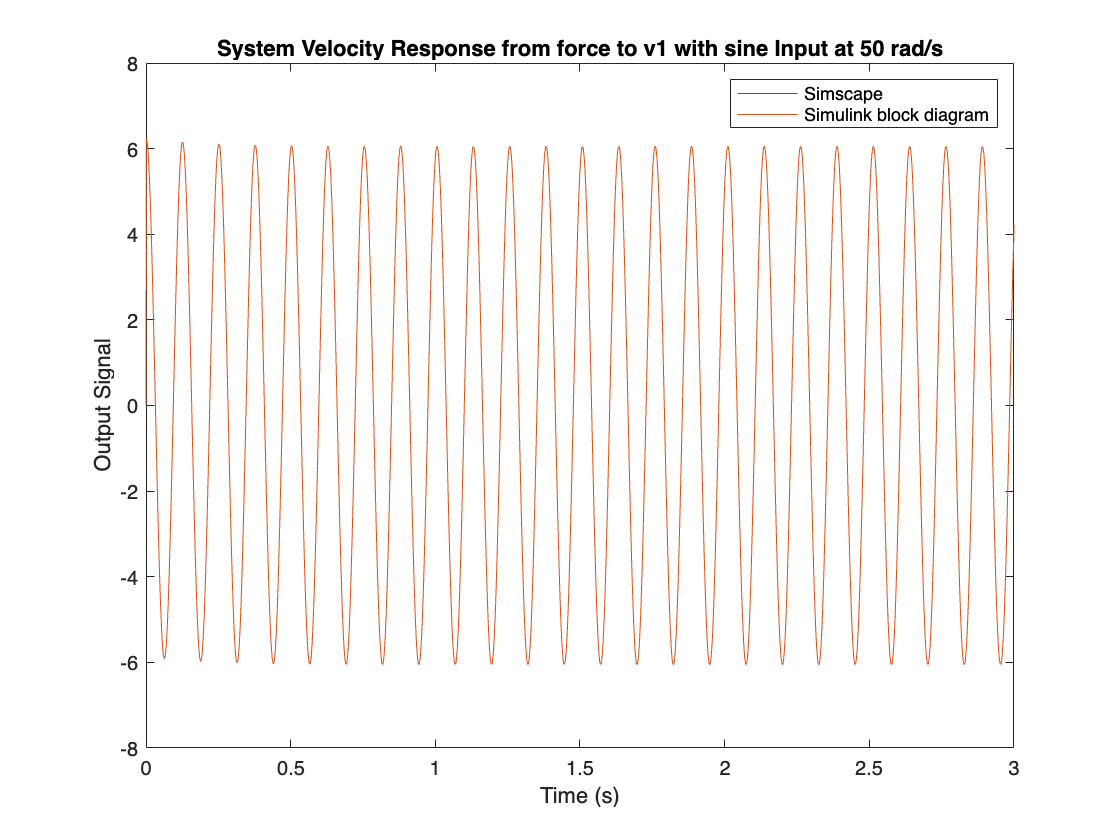

model_name = 'Part1_new2'; 
load_system(model_name);

runningtime = num2str(3);

set_param(model_name, 'StopTime', runningtime); 

input_type = 'sine';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval2'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval2'], 'Value', '0');
        
        
        frequency = num2str(50); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave2'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time12 = simOut.tout;
output_signal12 = simOut.logsout.getElement('Velocity 1 Sim 2,3 Ex.3').Values.Data; 

model_name = 'excercise1_3bd2'; 
load_system(model_name);

runningtime = num2str(3);

set_param(model_name, 'StopTime', runningtime); 
set_param(model_name, 'Solver', 'ode45');
set_param(model_name, 'MaxStep', '0.001');

input_type = 'sine';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = num2str(50); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time23 = simOut.tout;
output_signal23 = simOut.logsout.getElement('v1').Values.Data;

figure;

runningtimeint = str2num(runningtime);
tvec = linspace(0,runningtimeint,length(output_signal12));

plot(tvec, output_signal12)
hold on
plot(sim_time23, output_signal23)
legend("Simscape", "Simulink block diagram")

title(['System Velocity Response from force to v1 with ' input_type ' Input at 50 rad/s']);
xlabel('Time (s)');
ylabel('Output Signal');
hold off

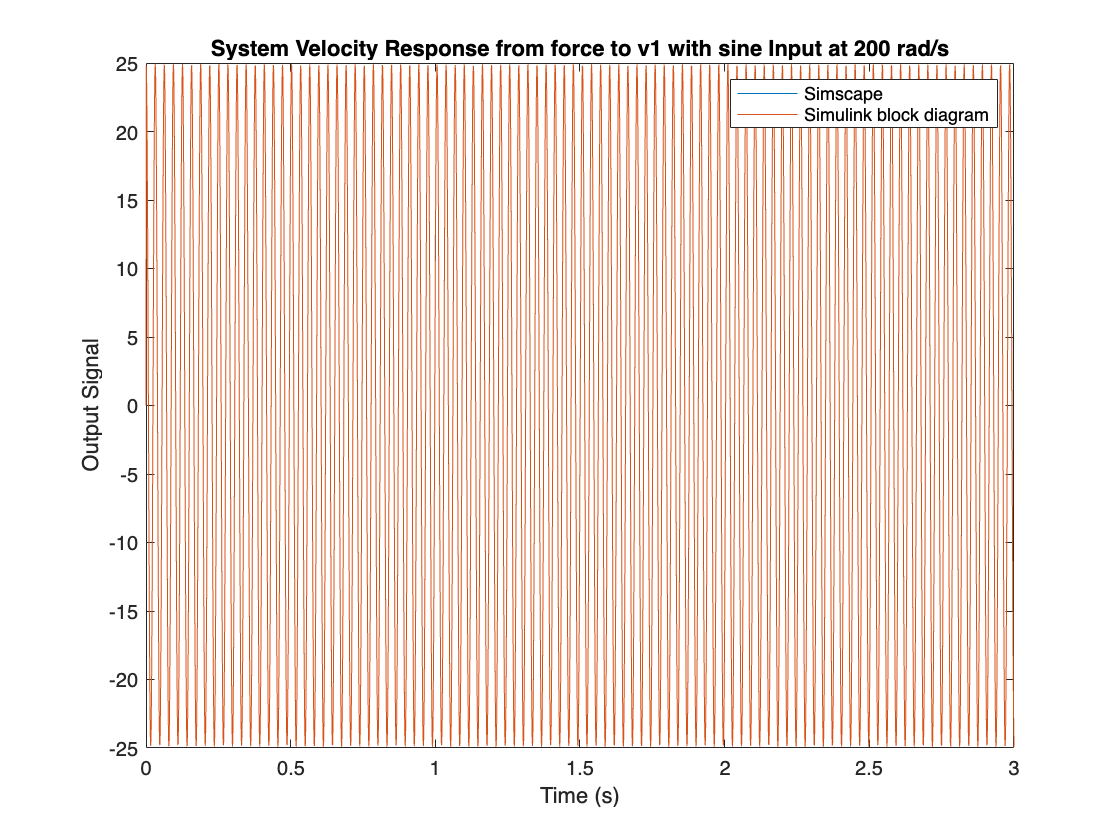

model_name = 'Part1_new2'; 
load_system(model_name);

runningtime = num2str(3);

set_param(model_name, 'StopTime', runningtime); 

input_type = 'sine';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval2'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval2'], 'Value', '0');
        
        
        frequency = num2str(200); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave2'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time12 = simOut.tout;
output_signal12 = simOut.logsout.getElement('Velocity 1 Sim 2,3 Ex.3').Values.Data; 

model_name = 'excercise1_3bd2'; 
load_system(model_name);

runningtime = num2str(3);

set_param(model_name, 'StopTime', runningtime); 
set_param(model_name, 'Solver', 'ode45');
set_param(model_name, 'MaxStep', '0.001');

input_type = 'sine';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = num2str(200); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time23 = simOut.tout;
output_signal23 = simOut.logsout.getElement('v1').Values.Data;

figure;

runningtimeint = str2num(runningtime);
tvec = linspace(0,runningtimeint,length(output_signal12));

plot(tvec, output_signal12)
hold on
plot(sim_time23, output_signal23)
legend("Simscape", "Simulink block diagram")

title(['System Velocity Response from force to v1 with ' input_type ' Input at 200 rad/s']);
xlabel('Time (s)');
ylabel('Output Signal');
hold off

From these two plots it is possible to confirm the behavior of the system from force to velocity at v1 as it is shown in the bode diagram. The amplitude of the output signal rises with higher frequency as there is infinite gain towards higher frequencies. There are however some differences between the Simscape and the Simulink block diagram plots. This could be because they use a different solver, or maybe because they might use different timesteps. It could also be an effect of trying to simulate an "impossible" system in a simulation software meant to simulate real physical systems that means this system cant be properly simulated to where both Simulink and Simscape would return the same result. 